# Debauchies Wavelets

## Exercise 1a

Implement the function computeDBwavelet.m to compute arbitrary1 length Daubechies wavelets. The idea is to do this with the symbolic math toolbox. You will have to ensure that all the conditions for the Daubechies wavelet are properly implemented. 

%clear all; close all; clc

%test the function
computeDBwavelet(2)

ans =     0.4830    0.8365    0.2241   -0.1294
   -0.1294    0.2241    0.8365    0.4830


## Exercise 1b

Now verify the software for various Daubechies wavelets, in particular for filter lengths 2, 4, 6 and 12. For filter length 2, show that they are the same as the filter coefficients of the Haar wavelet. Indeed: only the conditions (i) and (ii) apply in this case, requirement (iii) is automatically satisfied and requirement (iv) is limited to requirement (ii). Also determine the filter coefficients f0, f1, f2, f3 of the Daubechies db4 wavelet. In addition to the conditions (i) and (ii), now also the conditions (iii) and (iv) must hold (with two zeros at z = −1). Next, compute the filter coefficients f0, f1, f2, f3, f4, f5 of the Daubechies db6 wavelet. Now the requirements (iii) and (iv) each yield two conditions (three zeros of F(z) are to be located at z = −1).

[f_1,g_1]=computeDBwavelet(1) %filter length 2

f_1 =     0.7071    0.7071


g_1 =     0.7071   -0.7071


%show that same coefs as Haar wavelet:
c=[1, 1]/sqrt(2) % low-pass

c =     0.7071    0.7071


d=[1, -1]/sqrt(2) % high-pass

d =     0.7071   -0.7071


As we can see,f1 = c and g1= d so db2 filters = Haar filters

%Also determine the filter coefficients f0, f1, f2, f3 of the Daubechies db4 wavelet.

[f_2,g_2]=computeDBwavelet(2) %filter length 4

f_2 =     0.4830    0.8365    0.2241   -0.1294
   -0.1294    0.2241    0.8365    0.4830


g_2 =    -0.1294   -0.2241    0.8365   -0.4830
    0.4830   -0.8365    0.2241    0.1294


From book:

g0=h3=...

g1=h2=...

g2=h1=...

g3=h0=...

LOOKS OK!

%Next, compute the filter coefficients f0, f1, f2, f3, f4, f5 of the Daubechies db6 wavelet

[f_3,g_3]=computeDBwavelet(3) %filter length 6

f_3 =     0.3327    0.8069    0.4599   -0.1350   -0.0854    0.0352
    0.0352   -0.0854   -0.1350    0.4599    0.8069    0.3327


g_3 =     0.0352    0.0854   -0.1350   -0.4599    0.8069   -0.3327
    0.3327   -0.8069    0.4599    0.1350   -0.0854   -0.0352


From book:

g0=h5=0.035226

g1=-h4=0.085441

g2=h3=-0.135011

g3=-h2=-0.459878

g4=h1=0.806892

g5=-h0=-0.332671

LOOKS OK!

## Exercise 1c

Adapt your software for longer length filters, such as length 12. The software should give you all possible solutions. However, as the filter length increases, Matlab will at some point “loose” solutions. I don’t know why. As the textbook explains the number of solutions increases as the filters get longer. One of the solutions should be the Daubechies wavelet. Ensure that you display the conditions such that you can check your software. You can easily verify the correctness of what you have done by comparing against the actual Daubechies filters. Watch out for scaling differences though. For example on https://en.wikipedia.org/wiki/Daubechies_wavelet you can find the wavelet coefficients till length 20, but you’ll have to divide them by √ (2) to get the same scaling as f has.

[f_6,g_6] = computeDBwavelet(6) %filter length 12

f_6 =     0.0154    0.0035   -0.1180   -0.0483    0.4911    0.7876    0.3379   -0.0726   -0.0211    0.0447    0.0018   -0.0078
   -0.0078    0.0018    0.0447   -0.0211   -0.0726    0.3379    0.7876    0.4911   -0.0483   -0.1180    0.0035    0.0154
    0.0221    0.0499    0.0166    0.1515    0.6147    0.7126    0.1249   -0.2509   -0.0835    0.0494    0.0123   -0.0054
   -0.0054    0.0123    0.0494   -0.0835   -0.2509    0.1249    0.7126    0.6147    0.1515    0.0166    0.0499    0.0221
    0.0031   -0.0060   -0.0137    0.0513    0.0358   -0.1475    0.0472    0.6458    0.7115    0.2028   -0.0767   -0.0393
   -0.0393   -0.0767    0.2028    0.7115    0.6458    0.0472   -0.1475    0.0358    0.0513   -0.0137   -0.0060    0.0031
    0.1115    0.4946    0.7511    0.3153   -0.2263   -0.1298    0.0975    0.0275   -0.0316    0.0006    0.0048   -0.0011
   -0.0011    0.0048    0.0006   -0.0316    0.0275    0.0975   -0.1298   -0.2263    0.3153    0.7511    0.4946    0.1115


g_6 =    -0.0078   -0.0018    0.0447    0.0211   -0.0726   -0.3379    0.7876   -0.4911   -0.0483    0.1180    0.0035   -0.0154
    0.0154   -0.0035   -0.1180    0.0483    0.4911   -0.7876    0.3379    0.0726   -0.0211   -0.0447    0.0018    0.0078
   -0.0054   -0.0123    0.0494    0.0835   -0.2509   -0.1249    0.7126   -0.6147    0.1515   -0.0166    0.0499   -0.0221
    0.0221   -0.0499    0.0166   -0.1515    0.6147   -0.7126    0.1249    0.2509   -0.0835   -0.0494    0.0123    0.0054
   -0.0393    0.0767    0.2028   -0.7115    0.6458   -0.0472   -0.1475   -0.0358    0.0513    0.0137   -0.0060   -0.0031
    0.0031    0.0060   -0.0137   -0.0513    0.0358    0.1475    0.0472   -0.6458    0.7115   -0.2028   -0.0767    0.0393
   -0.0011   -0.0048    0.0006    0.0316    0.0275   -0.0975   -0.1298    0.2263    0.3153   -0.7511    0.4946   -0.1115
    0.1115   -0.4946    0.7511   -0.3153   -0.2263    0.1298    0.0975   -0.0275   -0.0316   -0.0006    0.0048    0.0011


%check if correct answers with wikipedia

%First have to mulitply by sqrt2 as wiki as f/sqrt2

f_6 = f_6*sqrt(2)

f_6 =     0.0218    0.0049   -0.1669   -0.0683    0.6945    1.1139    0.4779   -0.1027   -0.0298    0.0633    0.0025   -0.0110
   -0.0110    0.0025    0.0633   -0.0298   -0.1027    0.4779    1.1139    0.6945   -0.0683   -0.1669    0.0049    0.0218
    0.0313    0.0706    0.0235    0.2143    0.8694    1.0077    0.1767   -0.3548   -0.1181    0.0699    0.0173   -0.0077
   -0.0077    0.0173    0.0699   -0.1181   -0.3548    0.1767    1.0077    0.8694    0.2143    0.0235    0.0706    0.0313
    0.0043   -0.0084   -0.0194    0.0725    0.0506   -0.2086    0.0667    0.9134    1.0062    0.2868   -0.1085   -0.0556
   -0.0556   -0.1085    0.2868    1.0062    0.9134    0.0667   -0.2086    0.0506    0.0725   -0.0194   -0.0084    0.0043
    0.1577    0.6995    1.0623    0.4458   -0.3200   -0.1835    0.1379    0.0389   -0.0447    0.0008    0.0068   -0.0015
   -0.0015    0.0068    0.0008   -0.0447    0.0389    0.1379   -0.1835   -0.3200    0.4458    1.0623    0.6995    0.1577


The 7th row has the same numbers as wikipedia!

why7?

## Exercise 2a

 Load the data in the file lab5 dataset1.mat. Use the function discreteWaveletTransform (but watch out with proper scaling!) to calculate a single step in the Daubechies 4 wavelet transform. This function takes the signal, the low-pass filter (e.g. the filter coefficients f) and the high-pass filter (alternating flip of f) as an input and returns the approximation coefficients and detail coefficients.

clear

load lab5_dataset1

s

s =      0     0     0     0     0     0     0     0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16   -16   -16   -16   -16   -16   -16   -16   -16   -16   -16


% Determine low- and high-pass filters
%% Daubechies 4 Lp and Hp filters:
%we know that they correspond to f_2 and g_2 from previously
[f_2,g_2]=computeDBwavelet(2) %filter length 4

f_2 =     0.4830    0.8365    0.2241   -0.1294
   -0.1294    0.2241    0.8365    0.4830


g_2 =    -0.1294   -0.2241    0.8365   -0.4830
    0.4830   -0.8365    0.2241    0.1294


Lp=f_2(1,:) %f0

Lp =     0.4830    0.8365    0.2241   -0.1294


Hp=g_2(1,:) %h3    %=f_2(4,:) because g0= h3

Hp =    -0.1294   -0.2241    0.8365   -0.4830


%it is obvious that Hp is flip of Lp
%hpf=flip(Lp)
% Calculate Daubechies 2 filter coefficients 
%should something be done here?

%Perform a single step in the decomposition
[a,d]=discreteWaveletTransform(s,Lp,Hp);

figure
plot((1:length(s))/2,s,1:length(a),a,1:length(d),d) 
legend({'original','approximation','detail'});

## Exercise 2b

Implement the function s = discreteWaveletreconstruction(a,d,Lp r,Hp r) to do the reconstruction and verify that the function is working properly. This should be easy to test, since you know the original signal before feeding it into discreteWaveletTransform. 

Some hints: 

– When using filter (and you must), use the time-reversed filters and add up the outcomes. This holds for all orthogonal wavelets. I’ve explained in class why that actually works. Probably in the beginning you have to wrap your head around wrapping (lecturer humor). Please remember that Matlab does additional zero-padding. The trick after that (since you get a longer output than input due to zero padding) is to keep what you must. To do this: 

        ∗ Start with upsampling first and then the wrapping. (Then you have some more fine control.) The upsampling starts with a value, then a zero, etc. (I do fancy Matlab and use “kron” for that) 

        ∗ To ensure periodic extension and perfect reconstruction for a filter of length n first concatenate a copy of the n last samples of the signal to the front. (Our filter will not be causal, just to keep things simple.) Also concatenate the first signal value to the end. 

        ∗ Perform the filtering. 

        ∗ If you did it in this order, it should be easy to extract the right coefficients.

– Test this for a 1D signal for a single scale. Likely you will see shifted outputs (outputs that are time delayed or time advanced) when testing. , If you get completely different values, this indicates that likely there is something wrong with your filters. If you merely get shifted outcomes, then likely it is a wrapping/selection issue. 

– Looking at convolution matrices actually helped me to understand how it works with filters. Please be aware however, that an approach using convolution matrices in its implementation instead of filters is not an acceptable one. 

– I’ve included the function testWaveletRecon.m to help you test a bit. Note that the coefficients also have a finite accuracy, hence there are always very small errors. 

Lp_r=fliplr(Lp);
Hp_r=fliplr(Hp);
recons = discreteWaveletreconstruction(a,d,Lp_r,Hp_r)

recons =    -0.0000
         0
         0
         0
         0
         0
         0
    0.0000
    1.0000
    2.0000


%transpose s for correct dimensions
% s=s'
figure;

plot(s, 'DisplayName','orginal signal')
hold on
plot(recons, 'DisplayName', 'reconstructed signal')
hold off
legend('-DynamicLegend')

We can see that the signal is propery reconstructed!

## Exercise 2c

Calculate four scales in the multiresolution analysis of the dataset, using a ”logarithmic tree” of Daubechies 4 filter banks. For that, implement the wldecom and wlrecon functions. The output of this function should be an arrayC of the form: C = [app.coef.(J − j)|det.coef.(J − j)| . . . |det.coef.(J)]

%Perform a 4-level wavelet decomposition
C = wldecom(s,4,Lp,Hp)

C =    42.0533  -67.9854    0.4764   45.4556   15.1906   -9.9453   -5.4763   -7.4968   -0.4470    1.2370    0.4470   13.5230  -25.3915   -2.4740    1.5800   -0.3430   -0.2333   -0.5413   -0.0000    0.0000    0.2333    0.5413   -0.0000   -0.0000    5.4641  -19.3205    0.0000    0.0000   -0.4665   -1.0825    0.4665    1.0825         0         0         0   -0.4830    0.0000         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.4830    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


%perform the reconstruction
%DOES NOT FUCKING WORK
rC = wlrecon(C, 4, Lp, Hp)

rC =    -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    1.0000    2.0000    3.0000    4.0000    5.0000    6.0000    7.0000    8.0000    9.0000   10.0000   11.0000   12.0000   13.0000   14.0000   15.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000  -16.0000  -16.0000  -16.0000  -16.0000  -16.0000  -16.0000  -16.0000  -16.0000  -16.0000  -16.0000


tolerance = 1e-6;

check = all(abs(rC - s) < tolerance);

if check
    disp('reconstruction worked properly');
else
    disp('reconstruction did not work');
end

reconstruction worked properly


## Exercise 2d

Use the function plotWaveletDecompositionMap.m to display the wavelet decomposition of the dataset. This function takes C, the number of levels in the decomposition and the length of the dataset as an input argument.

%Plot the decomposition

plotWaveletDecompositionMap(C,4,64);

## Exercise 2e

Repeat b) and c) for lab5 dataset2.mat.

%Repeat for dataset2 Load the data
clear
load lab5_dataset2

%following is from 2a)

[f_2,g_2]=computeDBwavelet(2) %filter length 4

f_2 =     0.4830    0.8365    0.2241   -0.1294
   -0.1294    0.2241    0.8365    0.4830


g_2 =    -0.1294   -0.2241    0.8365   -0.4830
    0.4830   -0.8365    0.2241    0.1294


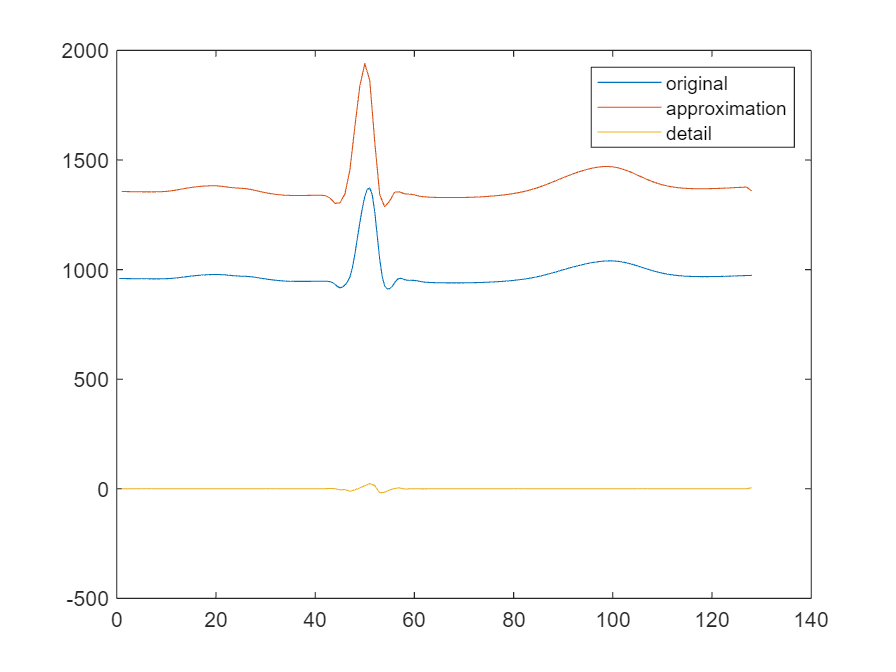

Lp=f_2(1,:);%f0
Hp=g_2(1,:); %h3    %=f_2(4,:) because g0= h3

%Perform a single step in the decomposition
[a,d]=discreteWaveletTransform(s,Lp,Hp);

figure
plot((1:length(s))/2,s,1:length(a),a,1:length(d),d) 
legend({'original','approximation','detail'});

b)

Lp_r=fliplr(Lp);
Hp_r=fliplr(Hp);
recons = discreteWaveletreconstruction(a,d,Lp_r,Hp_r)

recons = 1.0e+03 *

    0.9597
    0.9594
    0.9592
    0.9590
    0.9588
    0.9586
    0.9585
    0.9583
    0.9582
    0.9581


%transpose s for correct dimensions
% s=s'
figure;

plot(s, 'DisplayName','orginal signal')
hold on
plot(recons, 'DisplayName', 'reconstructed signal')
hold off
legend('-DynamicLegend')

c)

%Perform a 4-level wavelet decomposition
C = wldecom(s,4,Lp,Hp)

C = 1.0e+03 *

    3.9001    3.8738    3.7942    3.7663    4.5737    3.7774    3.7759    3.7685    3.8308    3.9976    4.1488    4.0429    3.8810    3.8752    3.8532    3.8369   -0.0035    0.0134    0.0020   -0.0007   -0.2459    0.2823    0.0641   -0.0035   -0.0077   -0.0124    0.0151    0.0340   -0.0190   -0.0087    0.0122   -0.0146   -0.0006   -0.0029    0.0009    0.0029    0.0015    0.0029   -0.0019   -0.0027   -0.0004    0.0104   -0.1686    0.3794   -0.3290    0.0324   -0.0036   -0.0008   -0.0007   -0.0009


%perform the reconstruction
%DOES NOT FUCKING WORK
rC = wlrecon(C, 4, Lp, Hp)

rC = 1.0e+03 *

    0.9597    0.9594    0.9592    0.9590    0.9588    0.9586    0.9585    0.9583    0.9582    0.9581    0.9580    0.9579    0.9578    0.9578    0.9577    0.9577    0.9578    0.9580    0.9583    0.9586    0.9592    0.9599    0.9609    0.9620    0.9633    0.9647    0.9661    0.9676    0.9691    0.9704    0.9717    0.9728    0.9738    0.9747    0.9756    0.9762    0.9768    0.9773    0.9775    0.9776    0.9775    0.9771    0.9764    0.9755    0.9745    0.9733    0.9722    0.9713    0.9707    0.9702


tolerance = 1e-6;

check = all(abs(rC - s) < tolerance);

if check
    disp('reconstruction worked properly');
else
    disp('reconstruction did not work');
end

reconstruction worked properly


d)

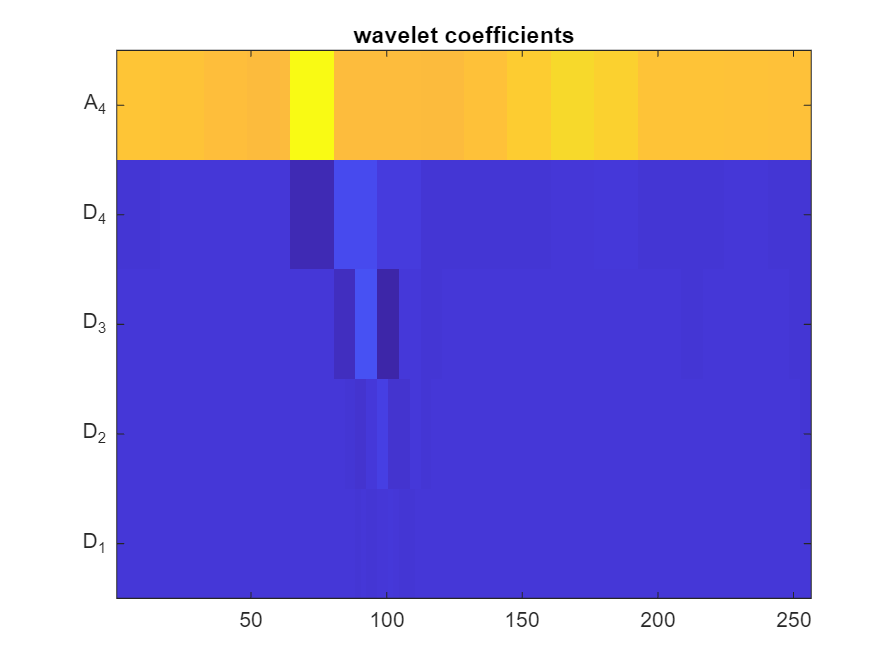

%Plot the decomposition

plotWaveletDecompositionMap(C,4,length(s));

## Exercise 3

%%maybe check the axes scales...

Now you should be able to build arbitrary Daubechies wavelets. Build Daubechies wavelet filter banks of filter lengths 4 and 6 and polynomial signals of orders from 1 to 3 and verify how polynomial signals are affected by these filter banks. Note that typically the wrapping causes a large value in the detail coefficients. Hence zoom in vertically to see what is happening.

We're going to test with a db4 and db6 wavelet

%given
[f4,g4]=computeDBwavelet(2);f4=f4(1,:);g4=g4(1,:);
[f6,g6]=computeDBwavelet(3);f6=f6(1,:);g6=g6(1,:);

And test that on various polynomials of order 1, 2 and 3.

t=linspace(0,2,256);
s1=3*t+1;
s2=0.5*t.^2;
s3=2*t.^3-t.^2;

%build approximation and detail coefficients for first order
[a1db4,d1db4] = discreteWaveletTransform(s1,f4,g4);
[a1db6,d1db6] = discreteWaveletTransform(s1,f6,g6);



First order 1

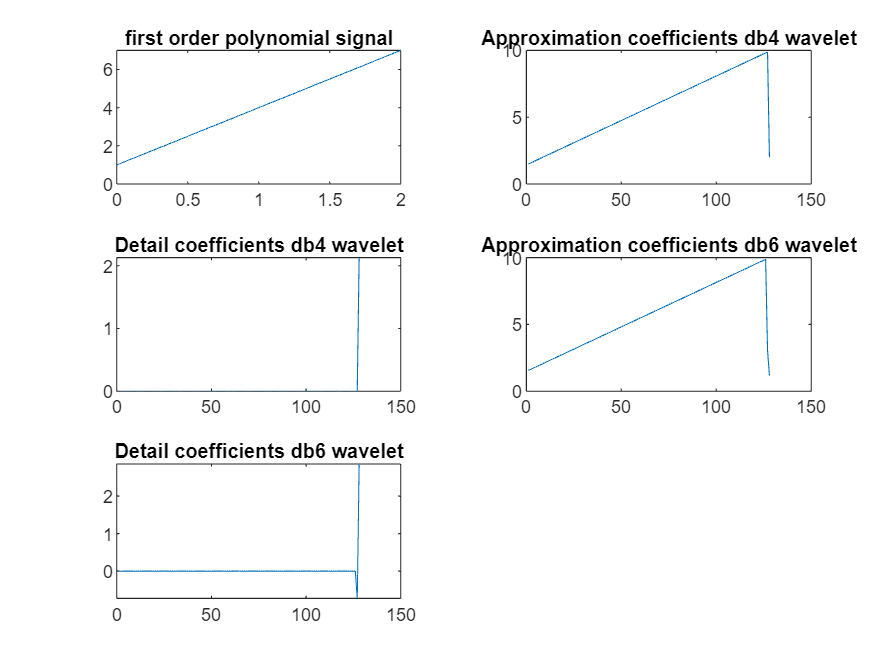

figure;
tiledlayout('flow');
nexttile;

plot(t, s1)
title('first order polynomial signal')
nexttile;

plot(1:length(a1db4),a1db4)
title('Approximation coefficients db4 wavelet')
nexttile;

plot(1:length(d1db4),d1db4)
title('Detail coefficients db4 wavelet')
nexttile;

plot(1:length(a1db6),a1db6)
title('Approximation coefficients db6 wavelet')
nexttile;

plot(1:length(d1db6),d1db6)
title('Detail coefficients db6 wavelet')

Order 2

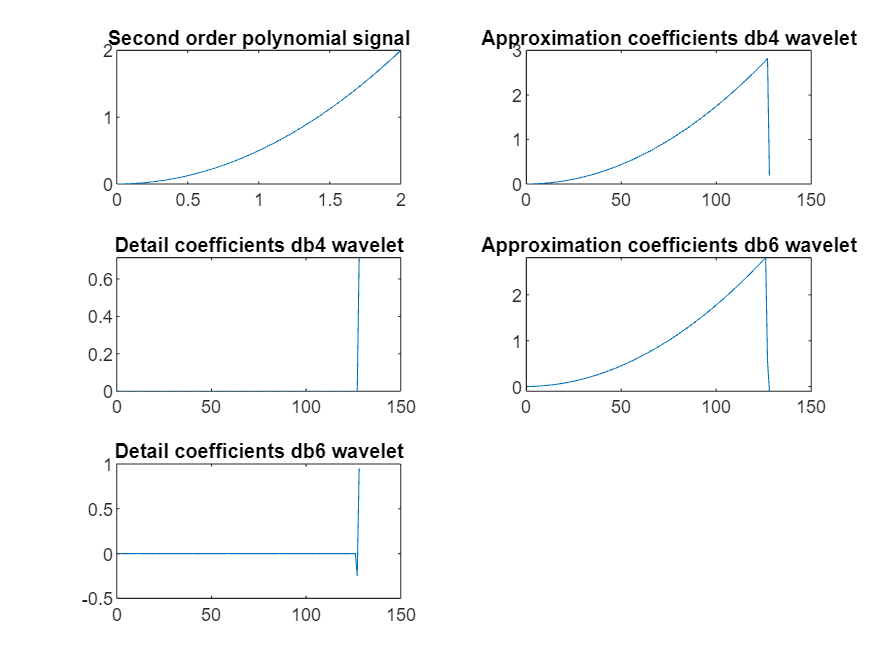


%build approximation and detail coefficients for second order
[a2db4,d2db4] = discreteWaveletTransform(s2,f4,g4);
[a2db6,d2db6] = discreteWaveletTransform(s2,f6,g6);


figure;
tiledlayout('flow');
nexttile

plot(t, s2)
title('Second order polynomial signal')

nexttile;
plot(1:length(a2db4),a2db4)
title('Approximation coefficients db4 wavelet')

nexttile;
plot(1:length(d2db4),d2db4)
title('Detail coefficients db4 wavelet')

nexttile;
plot(1:length(a2db6),a2db6)
title('Approximation coefficients db6 wavelet')

nexttile;
plot(1:length(d2db6),d2db6)
title('Detail coefficients db6 wavelet')

Order 3

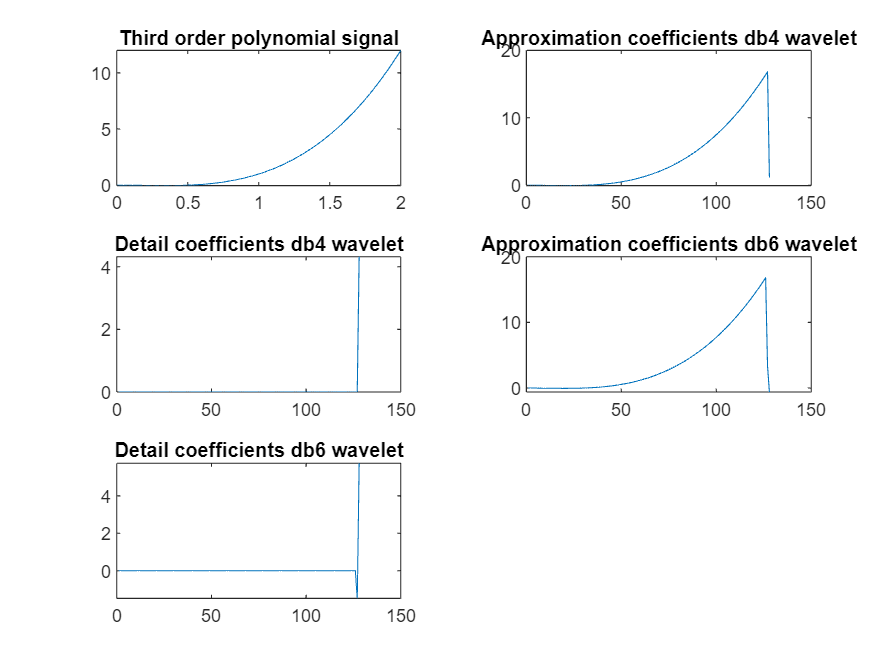

%build approximation and detail coefficients for third order
[a3db4,d3db4] = discreteWaveletTransform(s3,f4,g4);
[a3db6,d3db6] = discreteWaveletTransform(s3,f6,g6);

figure;
tiledlayout('flow');
nexttile;
plot(t,s3)
title('Third order polynomial signal')

nexttile;
plot(1:length(a3db4),a3db4)
title('Approximation coefficients db4 wavelet')

nexttile;
plot(1:length(d3db4),d3db4)
title('Detail coefficients db4 wavelet')

nexttile;
plot(1:length(a3db6),a3db6)
title('Approximation coefficients db6 wavelet')

nexttile;
plot(1:length(d3db6),d3db6)
title('Detail coefficients db6 wavelet')

## Exercise 4

Perform a 2D wavelet decompostion and reconstruction on lab5 dataset3.mat using the Daubechies wavelet of length 4 and using two levels. Ensure that you can do the 2D wavelet transform and reconstruction with Daubechies wavelets. **This sometimes pops up during exams!** As long as you don’t alter anything, you should get perfect reconstruction which is easily verified.

clear;
load lab5_dataset3
Lp=[0.4830    0.8365    0.2241   -0.1294];
Hp=fliplr(Lp).*[1 -1 1 -1]

Hp =    -0.1294   -0.2241    0.8365   -0.4830



s

s =    255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   



%  Plot the results
figure;
subplot(1,3,1);
imagesc(s)
colormap gray
axis square
axis off
title('original');


%Decompose following the same logic as in Lab4-Haar
[B1,H1,V1,D1] = wldecom_2(s,Lp, Hp);
[B2,H2,V2,D2]=wldecom_2(B1,Lp,Hp); %go to level2 wavelets but with approximation coefs (B) from level 1
%combine back approximation and detail coefficients together
lvl2=[B2 V2;H2 D2];
lvl1=[lvl2 V1;H1 D1];


%plot decomposition
imagesc(lvl1)
colormap gray
axis square
title('wavelet transform');

% Now reconstruct 
recon2 = wlrecon_2(B2,H2,V2,D2,Lp,Hp);
recon1 = wlrecon_2(recon2,H1,V1,D1,Lp,Hp)

recon1 =   254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804
  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804  254.9804

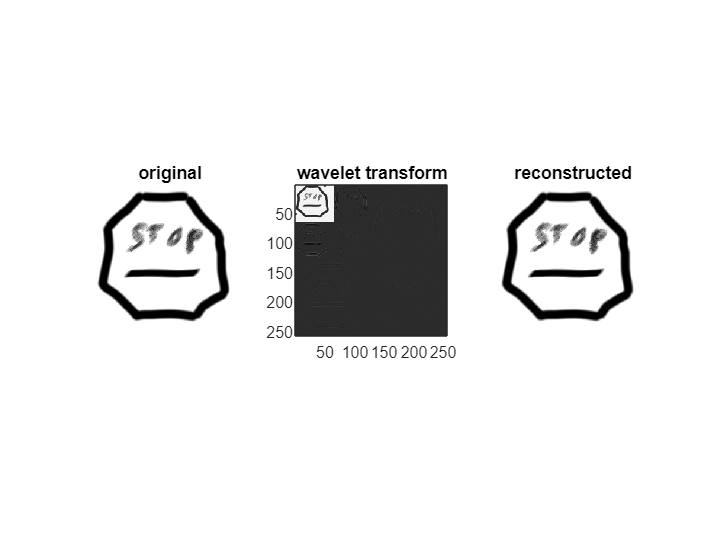


subplot(1,3,3);
imagesc(recon1)
colormap gray
axis square
axis off
title('reconstructed');

WRONG NUMBERS BUT CORRECT IMAGE :)

## Exercise 5

We wish to test what the effect of the Daubechies wavelet filters of length 6 are at various levels. We are first going to investigate this as follows: 

1. Compute the low- and highpass Daubechies wavelet filters of length 6

2. Create a signal s with a flat Fourier spectrum (i.e. S (ω) = 1 ∀ω). From the lecture on convolution and filtering part 1 you should know what that signal looks like. Plot the magnitude spectrum of this signal to verify

3. Compute 1 level of the wavelet decomposition of s to obtain the approximation coefficients a1 and detail coefficients d1. 

4. Plot the magnitudes Fourier coefficients of the signal that you obtain by reconstructing a1 alone (just pretend d1 is 0). 

5. Plot the magnitudes Fourier coefficients of the signal that you obtain by reconstructing d1 alone (just pretend a1 is 0).

6. Compute the second level of the wavelet decomposition of s to obtain the approximation coefficients a2 and detail coefficients d2. So compute the wavelet decomposition of a2.

7. Plot the magnitudes Fourier coefficients of the signal that you obtain by reconstructing a2 alone (just pretend all other coefficients are 0). 

8. Plot the magnitudes Fourier coefficients of the signal that you obtain by reconstructing d2 alone (just pretend all other coefficients are 0). 

What has been low-pass, band-pass and high-pass filtered? How do you think that will be for other levels?

first compute analysis and reconstruction filters

clear
[f,g]=computeDBwavelet(3)

f =     0.3327    0.8069    0.4599   -0.1350   -0.0854    0.0352
    0.0352   -0.0854   -0.1350    0.4599    0.8069    0.3327


g =     0.0352    0.0854   -0.1350   -0.4599    0.8069   -0.3327
    0.3327   -0.8069    0.4599    0.1350   -0.0854   -0.0352


Lp=f(1,:)

Lp =     0.3327    0.8069    0.4599   -0.1350   -0.0854    0.0352


Hp=g(1,:)

Hp =     0.0352    0.0854   -0.1350   -0.4599    0.8069   -0.3327


LpR=fliplr(Lp) % Reconstruction filters

LpR =     0.0352   -0.0854   -0.1350    0.4599    0.8069    0.3327


HpR=fliplr(Hp)

HpR =    -0.3327    0.8069   -0.4599   -0.1350    0.0854    0.0352


Create the signal and plot its Fourier magnitude spectrum

--> To build a signal that has a flat fourier spectrum, we can simply take the impulse function of the dirac delta function.

% % Define the signal s(t) using Dirac delta function
% t = linspace(-10, 10, 2048);
% % s = sinc(0.5 * t) % Using sinc function to approximate Dirac delta
% 
% s = dirac(t)
% figure 
% plot(t, s)
%% try something else

% x = -1023:1:1024;
% y = dirac(x);
% idx = y == Inf; % find Inf
% y(idx) = 1;     % set Inf to finite value
% stem(x,y)

%does not work! make it simpler
% s=y
s=zeros(1, 2048)

s =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


s(1)=1

s =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



figure
tiledlayout('flow');
nexttile
sM = abs(fft(s))

sM =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


plot(sM);
title('Fourier coefficients original signal')
axis tight

Perform a single step in the decomposition and compute the partial reconstructions with their magnitude spectra

[a1,d1]=discreteWaveletTransform(s,Lp,Hp);

nexttile
a1r = discreteWaveletreconstruction(a1, zeros(size(d1)), LpR, HpR);
a1rM= abs(fft(a1r)); %magnitude spectrum reconstruction
plot(a1rM);
title('Fourier coefficients reconstructed a_1')
axis tight
nexttile
d1r=discreteWaveletreconstruction(zeros(size(a1)), d1, LpR, HpR);
d1rM= abs(fft(d1r));
plot(d1rM);
title('Fourier coefficients reconstructed d_1')
axis tight

Perform a second level decomposition and compute the partial reconstructions with their magnitude spectra

[a2,d2]=discreteWaveletTransform(a1, Lp, Hp);
a2 = upsample(a2, 2);
d2 = upsample(d2, 2);

nexttile
a2r=discreteWaveletreconstruction(a2, zeros(size(d2)), LpR, HpR);
a2rM=abs(fft(a2r));
plot(a2rM);
title('Fourier coefficients reconstructed a_2')
axis tight

nexttile
d2r = discreteWaveletreconstruction(zeros(size(a2)), d2, LpR, HpR); % Replace with your actual reconstruction function
d2rM = abs(fftshift(fft(d2r)))

d2rM =     0.9771
    0.9771
    0.9771
    0.9771
    0.9771
    0.9770
    0.9770
    0.9769
    0.9768
    0.9768


plot(d2rM);
title('Fourier coefficients reconstructed d_2 after downsampling')
axis tight
nexttile

Perform a third level decomposition and compute the partial reconstructions with their magnitude spectra

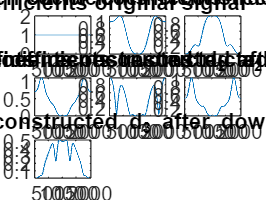

[a3,d3]=discreteWaveletTransform(a2,Lp,Hp);
a3 = upsample(a3, 2);
d3 = upsample(d3, 2);

a3r=discreteWaveletreconstruction(a3, zeros(size(d3)), LpR, HpR);
a3rM=abs(fft(a3r));
plot(a3rM);
title('Fourier coefficients reconstructed a_3 after downsampling')
axis tight
nexttile


d3r = discreteWaveletreconstruction(zeros(size(a3)), d3, LpR, HpR);
d3rM=abs(fft(d3r));
plot(d3rM);
title('Fourier coefficients reconstructed d_3 after downsampling')
axis tight